clc;clear;close all;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'IEDtwRas', 'IEDtwDas');
[forest, tf, scores] = iforest([IEDtwRas, IEDtwDas], "ContaminationFraction", 0.1);
IEDtwRas = IEDtwRas(scores <= forest.ScoreThreshold);
IEDtwDas = IEDtwDas(scores <= forest.ScoreThreshold);
[r, p] = corr(IEDtwRas, IEDtwDas, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4188

     0



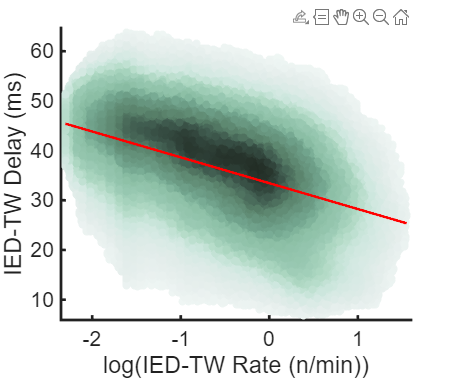

[~, Curve, ~] = f_polyfit(IEDtwRas, IEDtwDas, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(IEDtwRas, IEDtwDas, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(IEDtwRas)-0.05, max(IEDtwRas)+0.05]);
ylim([min(IEDtwDas)-1, max(IEDtwDas)+1]);
xlabel('log(IED-TW Rate (n/min))'); ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

clc; clear; close all;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'R_twDR_as'); R_twDR_as_true = R_twDR_as;
disp(mean(R_twDR_as_true(:)));

   -0.4183



disp(std(R_twDR_as_true(:)));

    0.0079



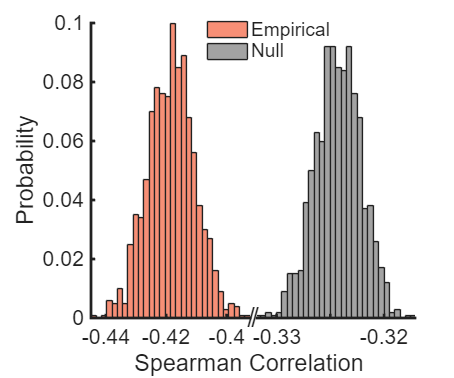

load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), ...
    'R_twDR_as'); R_twDR_as_null = mean(R_twDR_as, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
Ax1 = axes; set(Ax1, 'Position', [0.2, 0.16, 0.35, 0.78]);
histogram(R_twDR_as_true(:), 30, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability');
xlim([min(R_twDR_as_true(:)), max(R_twDR_as_true(:))]); 
ylim([0, 0.1]);
xlabel('Spearman Correlation', 'Position', [-0.3925, -0.011]);  ylabel('Probability');
annotation('textbox', [0.502, 0.105, 0.1, 0.1], 'String', '/', ...
           'EdgeColor', 'none', 'FontSize', 20, ...
           'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
annotation('textbox', [0.511, 0.105, 0.1, 0.1], 'String', '/', ...
           'EdgeColor', 'none', 'FontSize', 20, ...
           'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
set(Ax1, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
Ax2 = axes; set(Ax2, 'Position', [0.565, 0.16, 0.35, 0.78]);
histogram(R_twDR_as_true(:), 30, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability'); hold on;
histogram(R_twDR_as_null(:), 30, 'FaceColor', [0.4, 0.4, 0.4], ...
    'Normalization', 'probability'); hold off;
xlim([min(R_twDR_as_null(:)), max(R_twDR_as_null(:))]); 
ylim([0, 0.1]);
legend(["Empirical", "Null"], "Box", "off", "Position", [0.4488 0.8313 0.2863, 0.1230])
ylabel('Probability');
set(Ax2, 'YColor', 'none', 'ytick', [], 'yticklabel', [], ...
    'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = R_twDR_as_true(:); y = R_twDR_as_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x) + length(y) - 2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 0 z = -38.7201 Cliff Delta = -1 df = 1998


clc; clear; close all;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), 'R_twDR')
R_twDR_true = R_twDR'; trueStr = cell(length(R_twDR_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), 'R_twDR')
R_twDR_null = mean(R_twDR, 2); nullStr = cell(length(R_twDR_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_twDR_true; R_twDR_null]; Origin = [trueStr; nullStr];
disp(mean(R_twDR_true));

   -0.3313



disp(std(R_twDR_true));

    0.1678



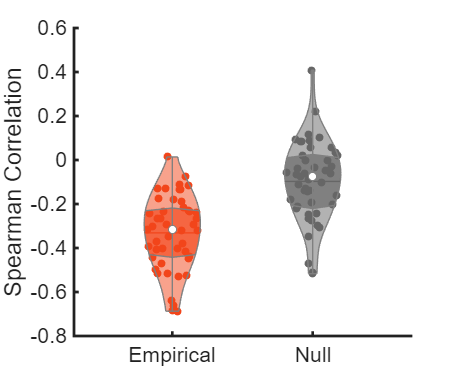

figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = R_twDR_true(:); y = R_twDR_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x) + length(y) - 2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 2.9755e-08 z = -5.5429 Cliff Delta = -0.6641 df = 92
